# PRÁCTICA 9: Descripción y Representación (1ª parte)

## PROPIEDADES DE UNA REGIÓN

- ‘all’, 'Area’, 'EulerNumber', 'Orientation', 'BoundingBox', 'Extent', 'Perimeter', 'Centroid', 'Extrema', 'ConvexArea', 'FilledArea', 'ConvexHull', 'FilledImage', 'ConvexImage', ' Image', 'Eccentricity', 'MajorAxisLength', 'EquivDiameter', 'MinorAxisLength'

NOTA: Si la imagen contiene más de una región binaria (conectada), el vector de salida tendrá una estructura para cada una de las regiones.

#### EJEMPLO

#### EJERCICIO 1

Cargue las imágenes “Classification\Parts00.png” y “Gears\Parts 01.jpg” (im1 e im2) y obtenga la binarización de ambas mediante umbralización óptima (imbinarize) (im1b e im2b), de tal manera que los objetos aparezcan en blanco sobre fondo negro (calcule la negada en caso necesario). Muestre en una figura las cuatro imágenes, subplot(2,2,…) .

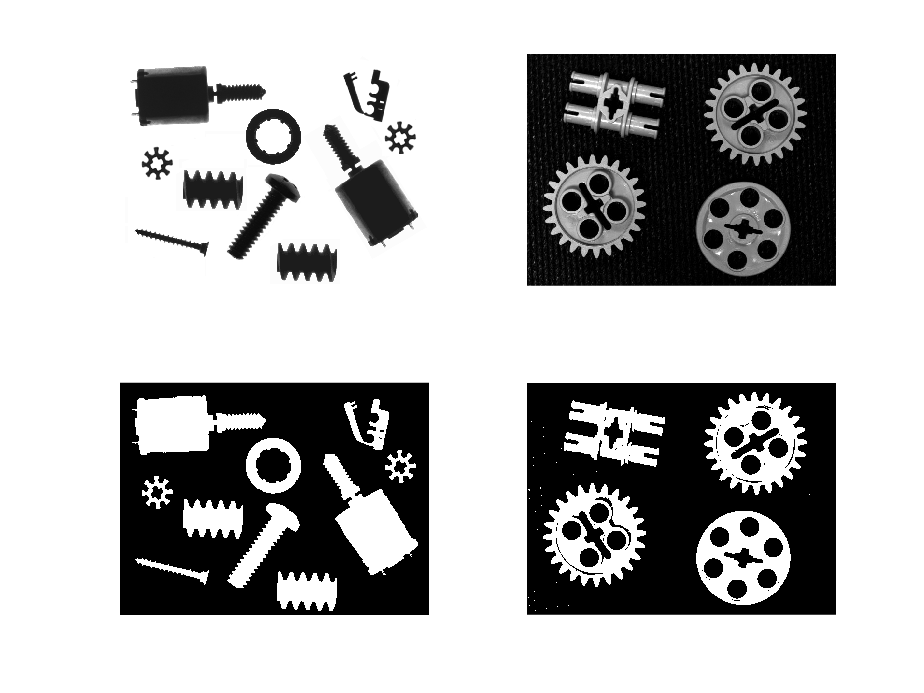

im1 = imread("Parts00.png");
im2 = imread("Parts 01.jpg");
im1b = 1-imbinarize(im1);
im2b = imbinarize(im2);
figure
subplot(221); imshow(im1);
subplot(222); imshow(im2);
subplot(223); imshow(im1b);
subplot(224); imshow(im2b);

#### EJERCICIO 2

Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90) (ob) y obtenga todas sus propiedades (regionprops). Compruebe su área, perímetro, área convexa y excentricidad.

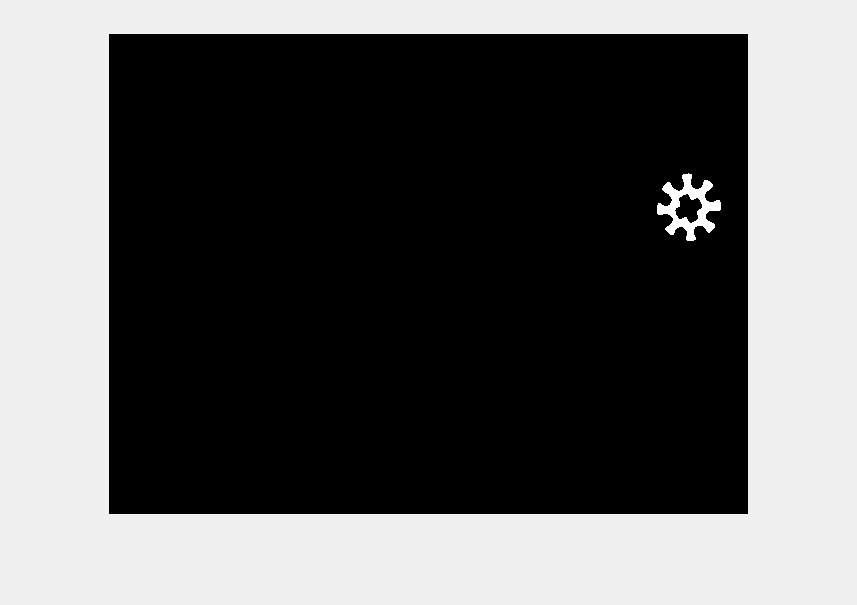

ob = vercre_isa(im1b, 0.90); %Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90)

pro = regionprops (ob,'all') % (ob) y obtenga todas sus propiedades (regionprops). 

pro = struct with fields:
                   Area: 1716
               Centroid: [580.4615 173.7855]
            BoundingBox: [548.5000 139.5000 64 68]
            SubarrayIdx: {[1×68 double]  [1×64 double]}
        MajorAxisLength: 65.7874
        MinorAxisLength: 63.4868
           Eccentricity: 0.2621
            Orientation: -85.8073
             ConvexHull: [73×2 double]
            ConvexImage: [68×64 logical]
             ConvexArea: 3289
            Circularity: 0.1956
                  Image: [68×64 logical]
            FilledImage: [68×64 logical]
             FilledArea: 2195
            EulerNumber: 0
                Extrema: [8×2 double]
          EquivDiameter: 46.7427
               Solidity: 0.5217
                 Extent: 0.3943
           PixelIdxList: [1716×1 double]
              PixelList: [1716×2 double]
              Perimeter: 328.8900
           PerimeterOld: 347.3625
       MaxFeretDiameter: 68.2642
          MaxFeretAngle: -95.0425
    MaxFeretCoordinates: [2

pro.Area % Compruebe su área,

ans = 1716

pro.Perimeter  % perímetro, 

ans = 328.8900

pro.ConvexArea % área convexa y 

ans = 3289

pro.Eccentricity % excentricidad.

ans = 0.2621

#### EJERCICIO 3

Muestre en una figura una imagen que contenga el objeto segmentado del ejercicio anterior en rojo sobre la imagen original y un asterisco marcando su centroide (‘Centroid’). 

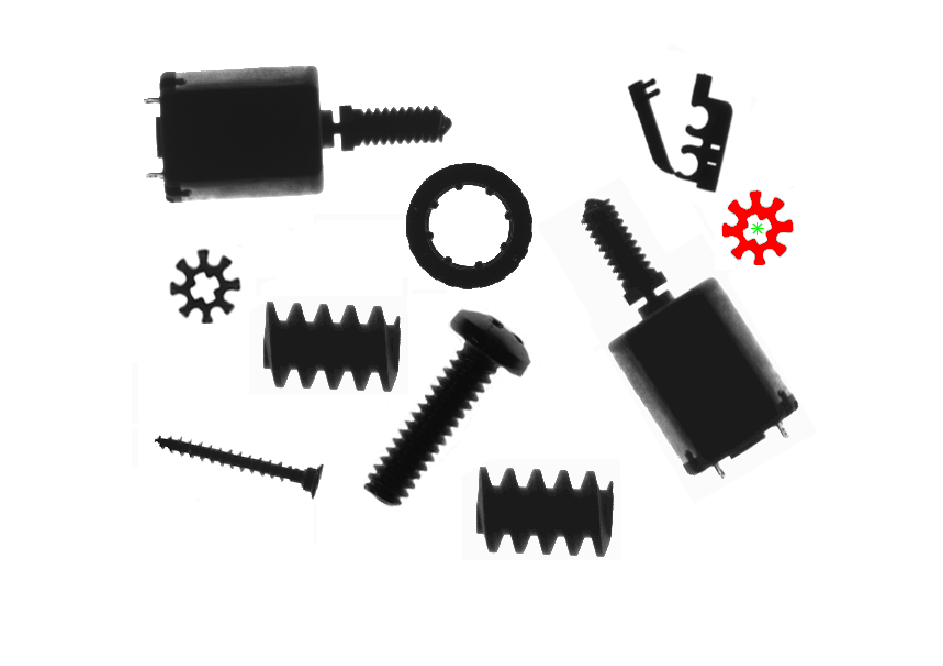

figure;
%double(im1(1,1))
%ob(1,1)
%[gray(255);1 0 0]
imshow(double(im1).*not(ob)+ob*256, [gray(255);1 0 0]); % paleta con fila adicional en rojo para valor 256
hold on;
plot(pro.Centroid(1),pro.Centroid(2), '*g');

En otra figura represente la región segmentada (‘Image’), el cerco convexo de la región (‘ConvexImage’), la región rellena (‘FilledImage’) y diferencia convexa (‘ConvexImage’ – ‘FilledImage’). suplot (2,2,…)

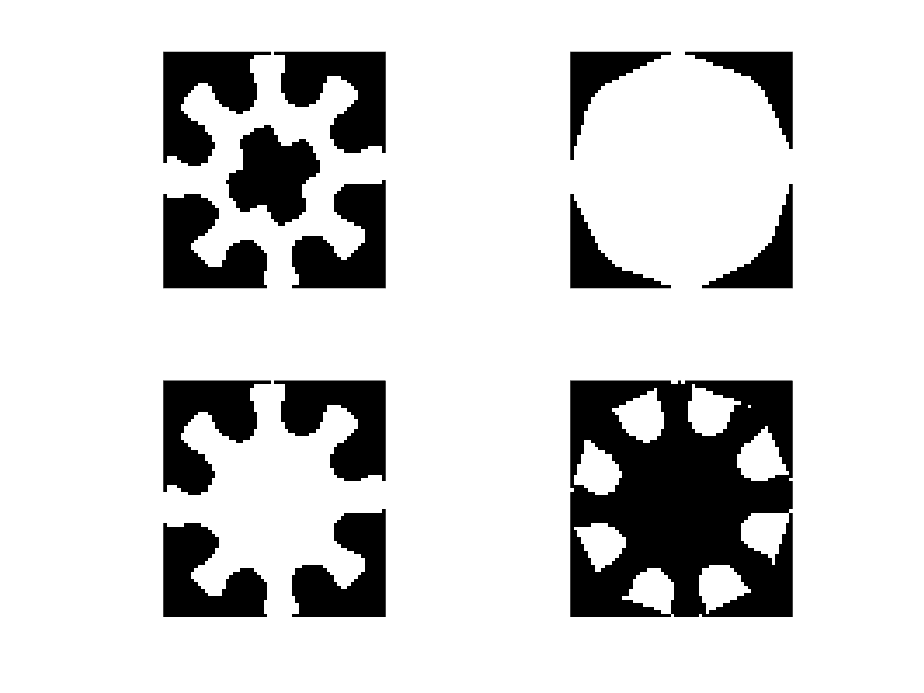

figure
subplot(2,2,1);imshow(pro.Image);
subplot(222); imshow(pro.ConvexImage);
subplot(223); imshow(pro.FilledImage);
subplot(224); imshow(pro.ConvexImage-pro.FilledImage);

NOTA: Para mostrar la región en rojo (ob) sobre la imagen puede emplear el código:

suponiendo que ‘im’ contiene la imagen original y ‘ob’ el objeto segmentado binario.

#### EJERCICIO 4

Repita los ejercicios 2 y 3 con varios objetos.

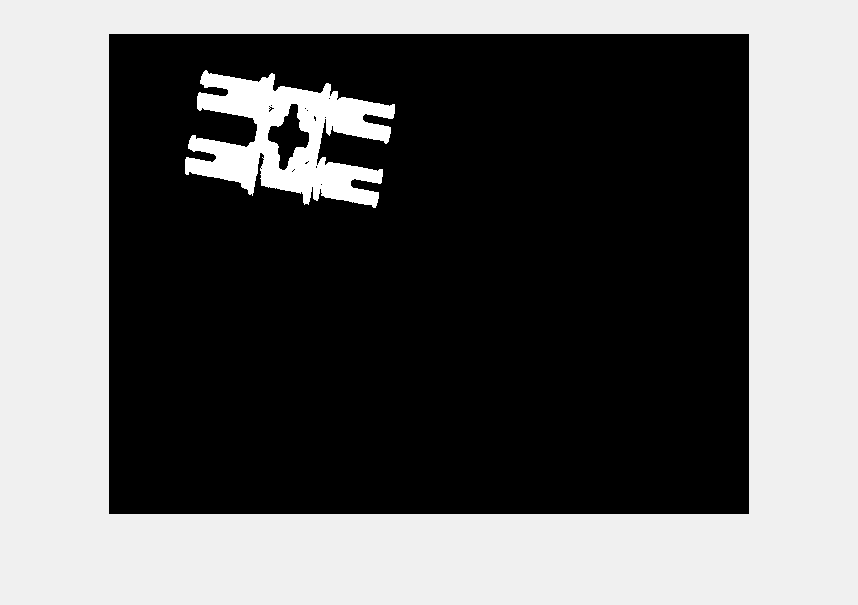

figure
ob = vercre_isa(im2b, 0.90); %Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90)

pro = regionprops (ob,'all') % (ob) y obtenga todas sus propiedades (regionprops);

pro = struct with fields:
                   Area: 14340
               Centroid: [180.4679 105.4759]
            BoundingBox: [76.5000 36.5000 210 138]
            SubarrayIdx: {[1×138 double]  [1×210 double]}
        MajorAxisLength: 213.7177
        MinorAxisLength: 137.2736
           Eccentricity: 0.7664
            Orientation: -9.9051
             ConvexHull: [51×2 double]
            ConvexImage: [138×210 logical]
             ConvexArea: 23221
            Circularity: 0.0994
                  Image: [138×210 logical]
            FilledImage: [138×210 logical]
             FilledArea: 15628
            EulerNumber: -17
                Extrema: [8×2 double]
          EquivDiameter: 135.1231
               Solidity: 0.6175
                 Extent: 0.4948
           PixelIdxList: [14340×1 double]
              PixelList: [14340×2 double]
              Perimeter: 1.3436e+03
           PerimeterOld: 1.4135e+03
       MaxFeretDiameter: 221.3594
          MaxFeretAngle: 161.5651
    M

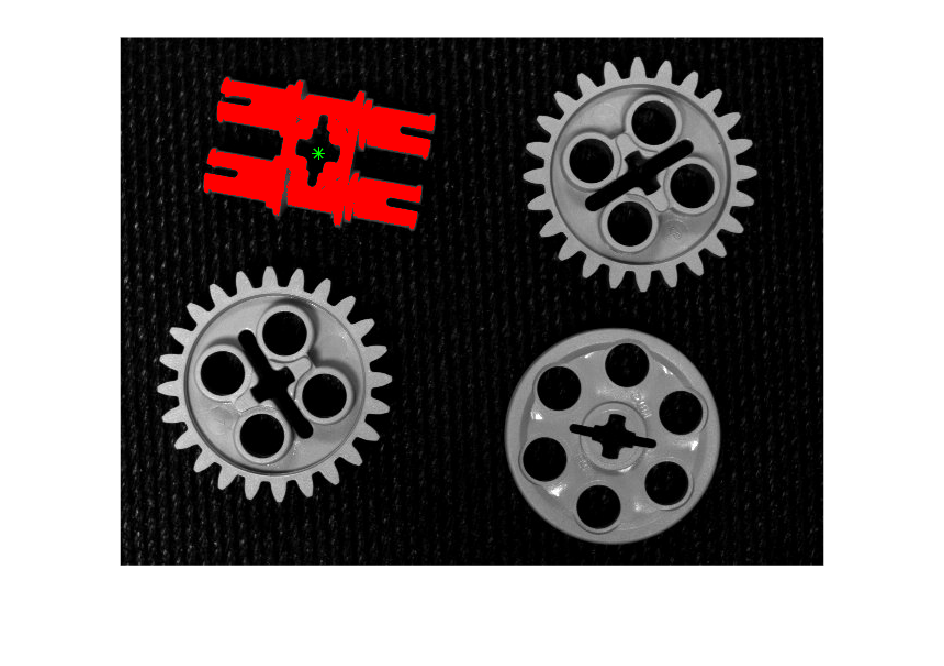

figure
imshow(double(im2).*not(ob)+ob*256, [gray(255);1 0 0]); % paleta con fila adicional en rojo para valor 256
hold on;
plot(pro.Centroid(1),pro.Centroid(2), '*g');

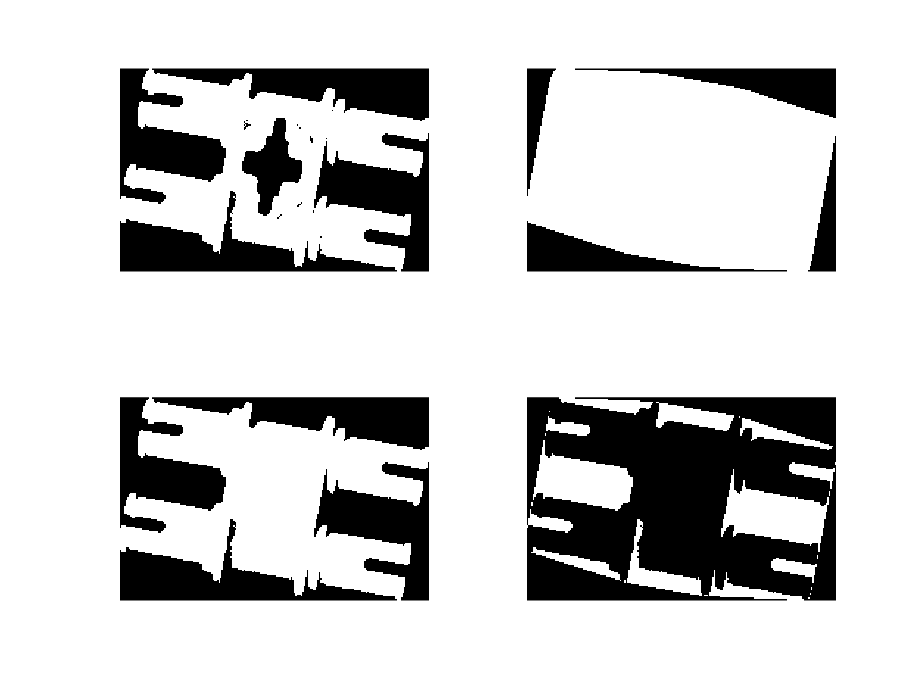

figure
subplot(2,2,1);imshow(pro.Image);
subplot(222); imshow(pro.ConvexImage);
subplot(223); imshow(pro.FilledImage);
subplot(224); imshow(pro.ConvexImage-pro.FilledImage);

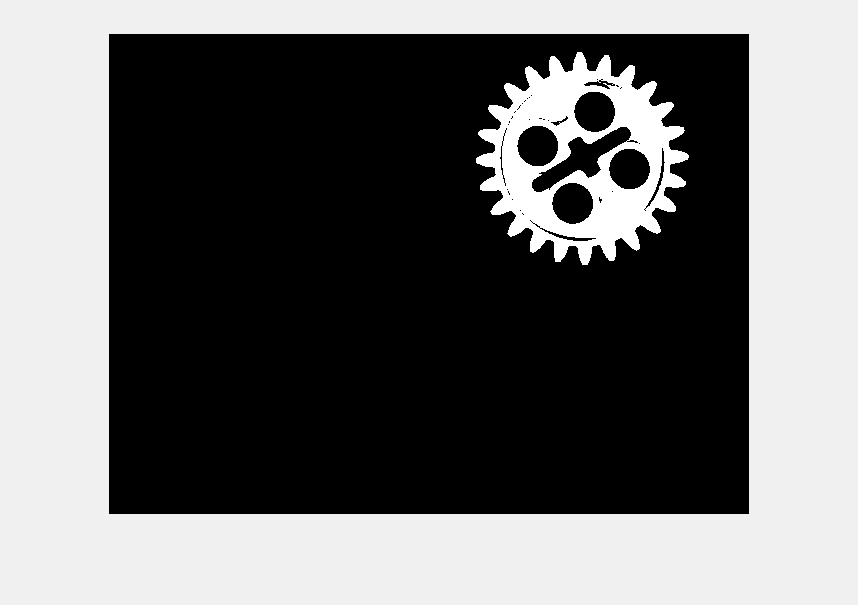

figure;
ob = vercre_isa(im2b, 0.90); %Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90)

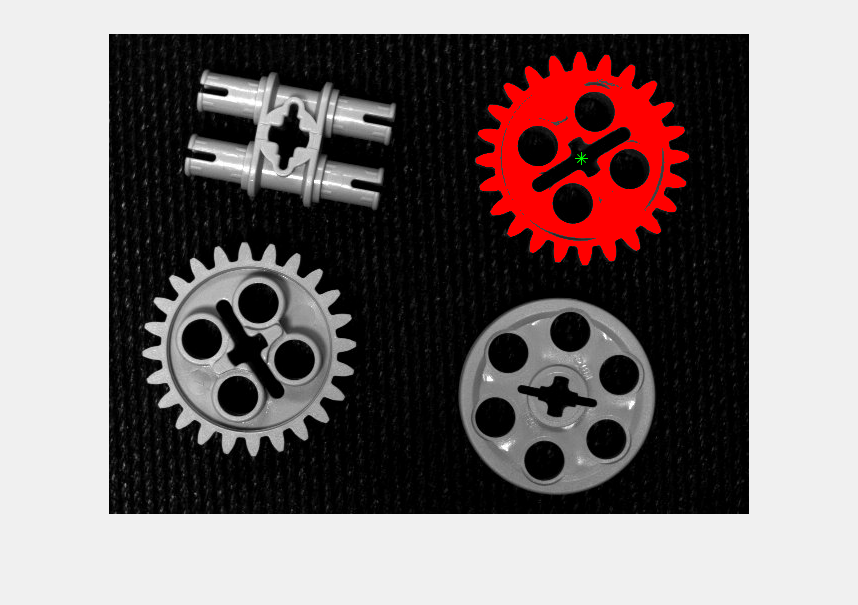

pro = regionprops (ob,'all'); % (ob) y obtenga todas sus propiedades (regionprops);
imshow(double(im2).*not(ob)+ob*256, [gray(255);1 0 0]); % paleta con fila adicional en rojo para valor 256
hold on;
plot(pro.Centroid(1),pro.Centroid(2), '*g');

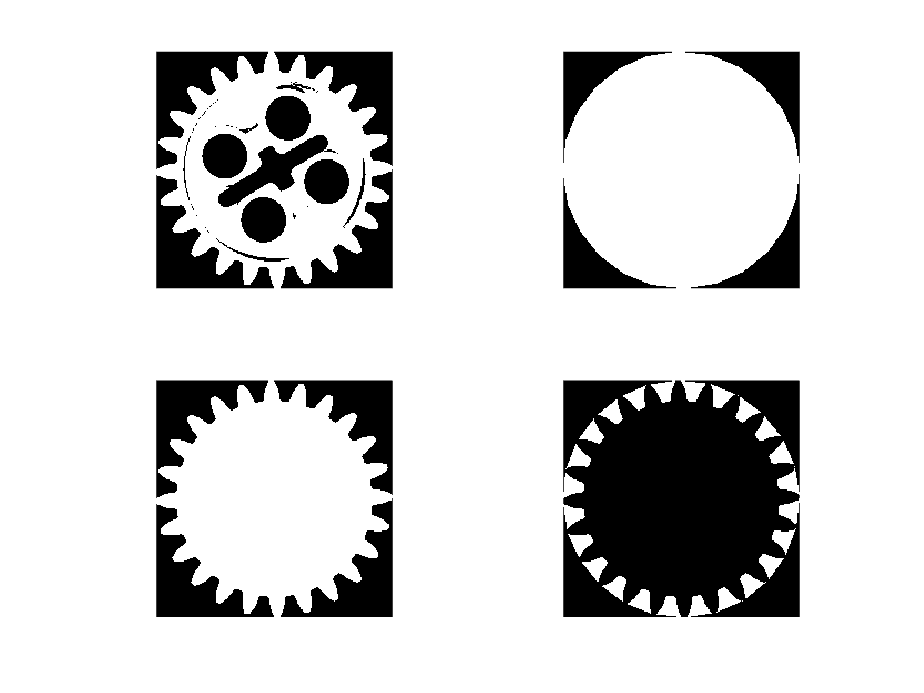

figure
subplot(2,2,1);imshow(pro.Image);
subplot(222); imshow(pro.ConvexImage);
subplot(223); imshow(pro.FilledImage);
subplot(224); imshow(pro.ConvexImage-pro.FilledImage);

## SIGNATURA DE UNA REGION

Devuelve una matriz de nx2, donde la primera columna es el ángulo en radianes y la segunda la distancia euclídea al centroide.

#### EJERCICIO 5

Estudie el algoritmo signatura_isa 

y utilícelo para obtener la signatura de todos los objetos de la imagen im1b. 

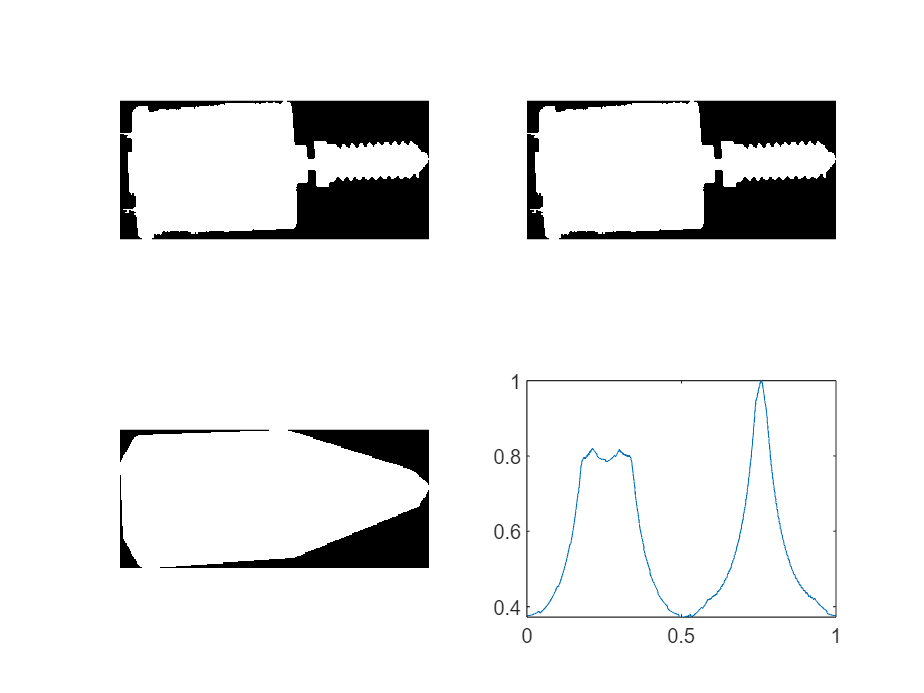

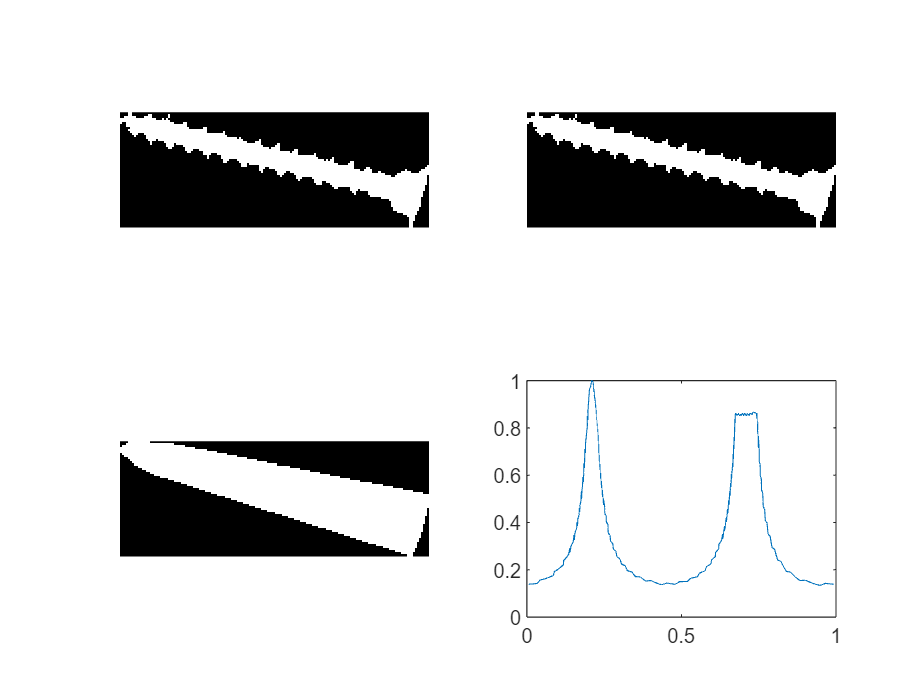

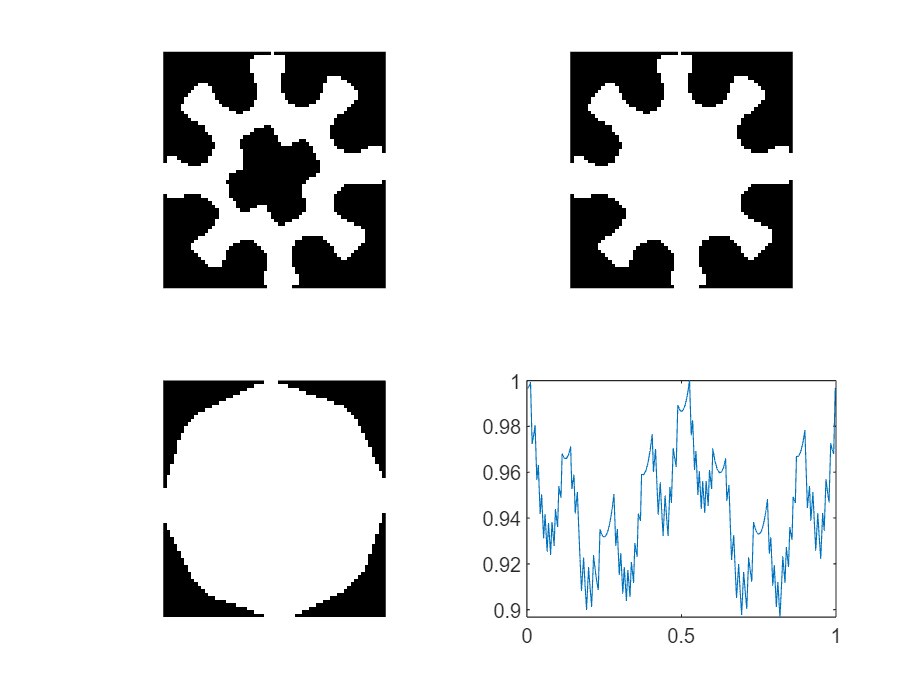

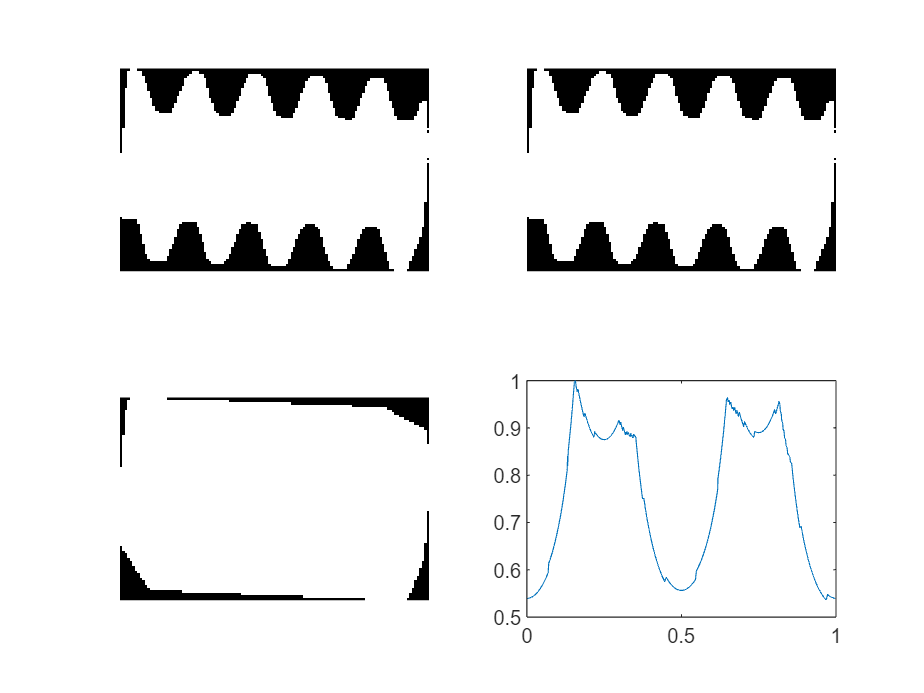

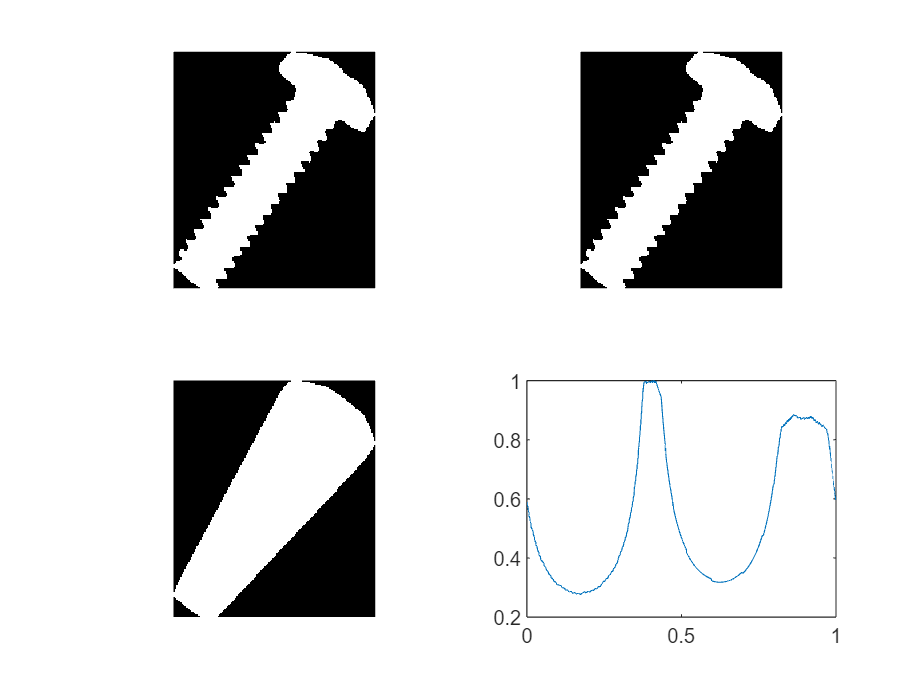

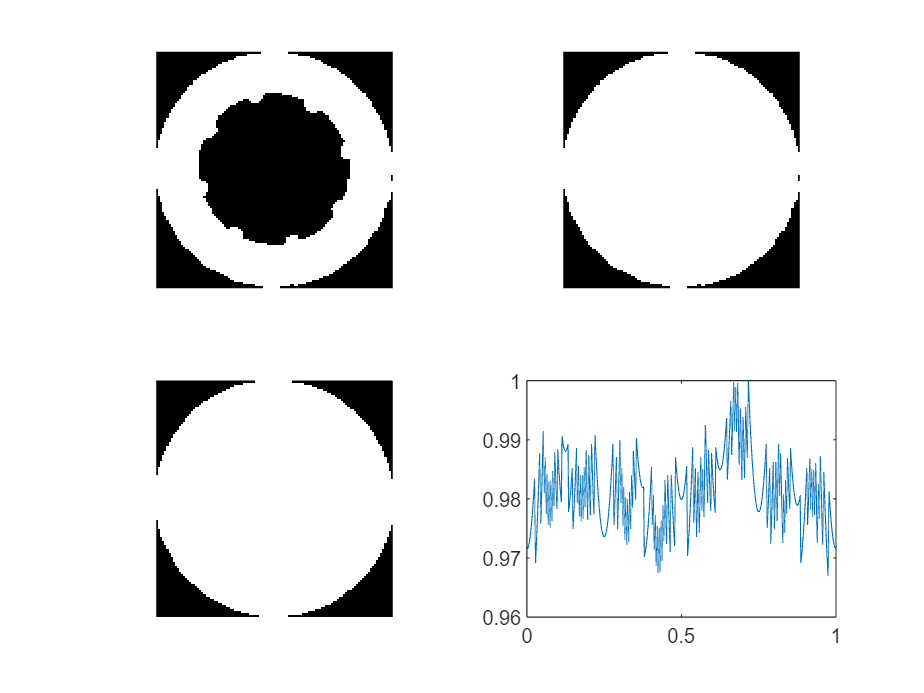

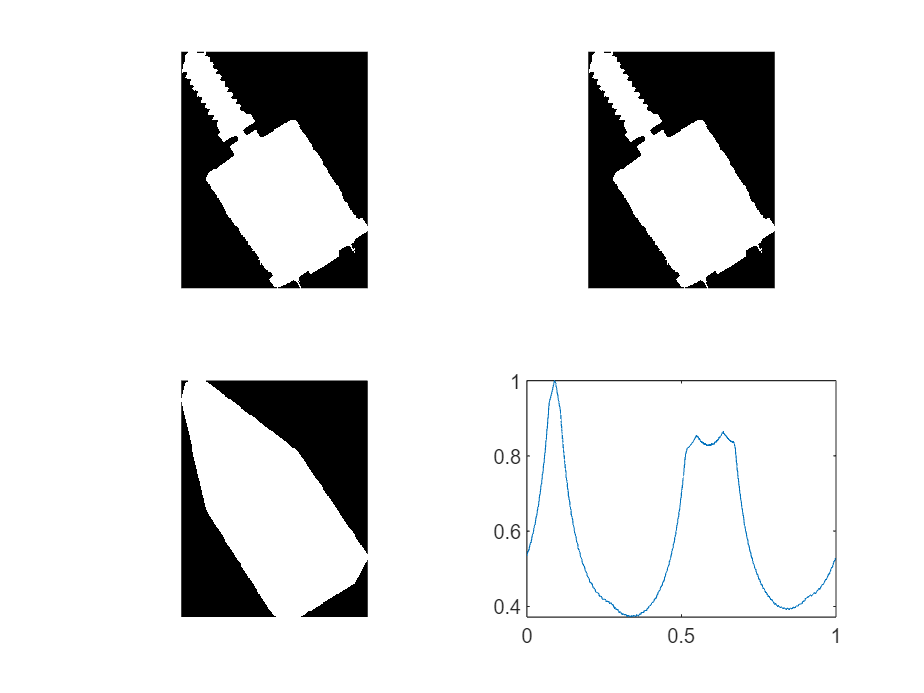

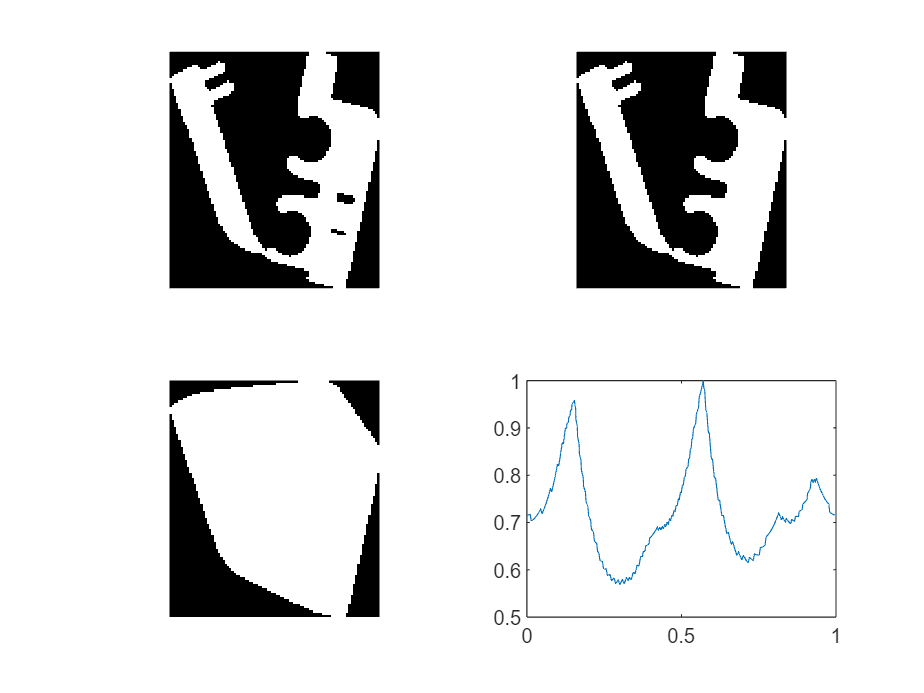

pro = regionprops(bwlabel(im1b), 'Image', 'Area','FilledImage', 'ConvexImage'); % 'all'); %'Image', );
for i = 1:numel(pro)
    %fprintf("i=%d, area=%d", i, pro(i).Area)
    if (pro(i).Area > 20)
        figure
        subplot(221); imshow(pro(i).Image); 
        subplot(222); imshow(pro(i).FilledImage);
        subplot(223); imshow(pro(i).ConvexImage);
        sig = signatura_isa(pro(i).ConvexImage); % Image);
        subplot(224); plot(sig(:,1)/(2*pi), sig(:,2));
    end

end

Para cada uno de los objetos segmentados represente en una figura la región binaria rellena (FilledImage), el cerco convexo (ConvexImage) y la signatura de cada una de ellas. (subplot(2,2,…)).

NOTA 1: Para representar la signatura hay que emplear el comando plot (ángulos, distancias),

NOTA 2: Obtenga las propiedades de todas las regiones conectadas de forma simultánea con regionprops y emplee un bucle for para procesar todos los objetos, descartando aquellos cuya área sea inferior a 20.

## ESQUELETO DE UNA REGION (ZANG Y SUEN)

#### EJERCICIO 6

Estudie el algoritmo veradel_isa 

y utilícelo para obtener el esqueleto de un objeto de la imagen im2, previamente segmentados (vercre_isa, umbral 90) y con sus huecos rellenos (‘FilledImage’). Repita el ejercicio anterior para cada tipo de objeto presente en la imagen im2 (polea, engranaje y eje)

imengra = vercre_isa(im2b, 0.90); 

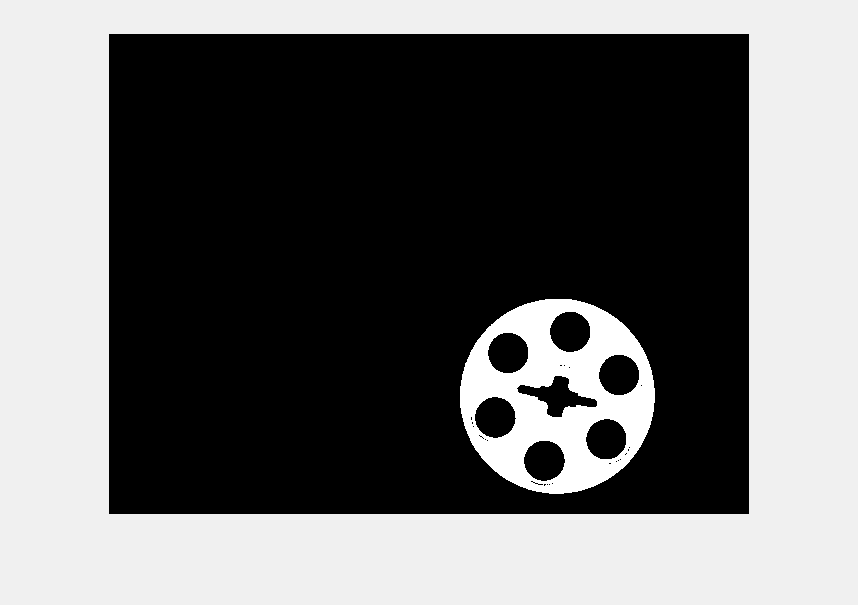

impolea = vercre_isa(im2b, 0.90);

imeje = vercre_isa(im2b, 0.9);

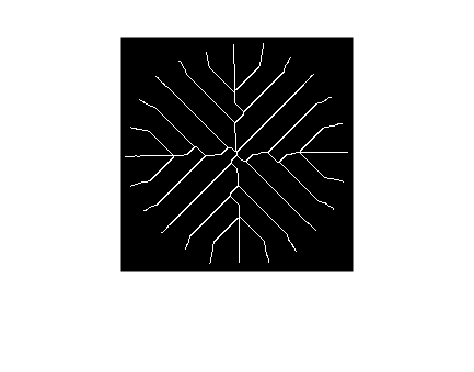

pro = regionprops (imengra,'FilledImage');
veradel_isa(pro.FilledImage);

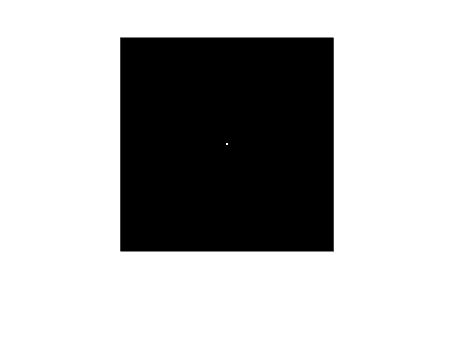

pro = regionprops (impolea,'FilledImage');
veradel_isa(pro.FilledImage);

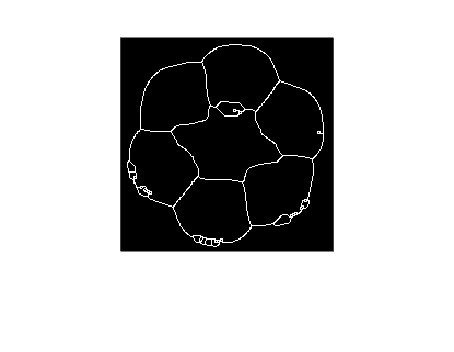

pro = regionprops (impolea,'Image');
veradel_isa(pro.Image);

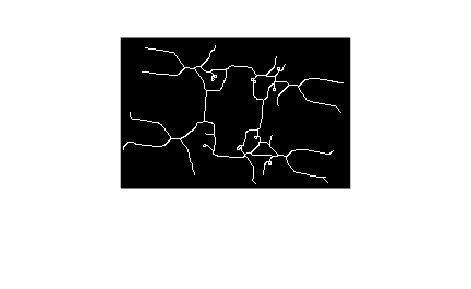

pro = regionprops (imeje,'Image');
veradel_isa(pro.Image);

#### EJERCICIO 7

Aplique un adelgazamiento a la imagen imb1 (todos los objetos en blanco sobre fondo en negro) y muestre en una figura la imagen original y los esqueletos de los objetos superpuestos en verde.

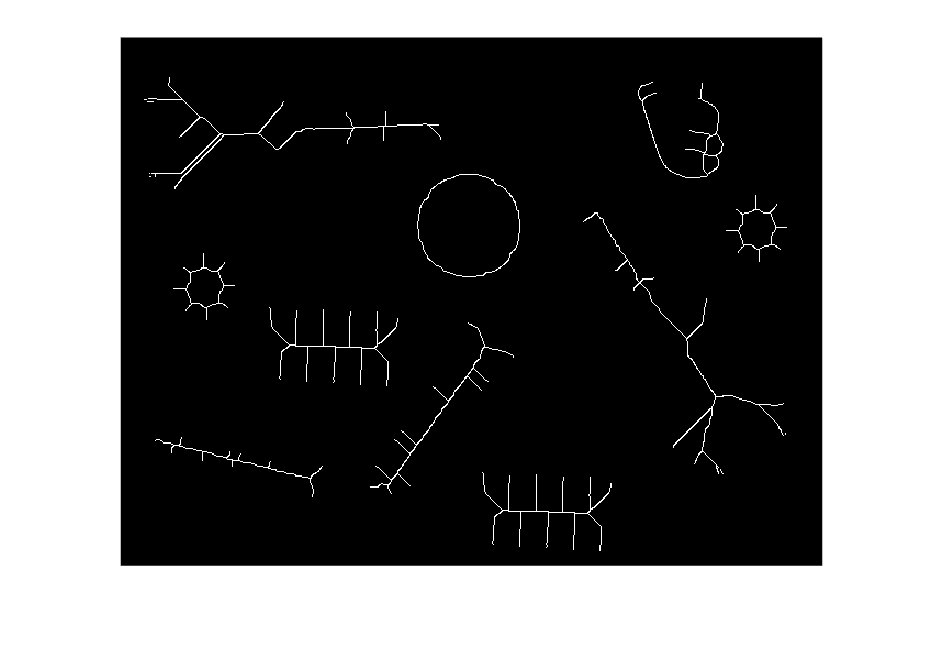

%pro = regionprops (im1b,'Image');
%esqueleto = veradel_isa(pro.Image);
esqueleto=veradel_isa(im1b);

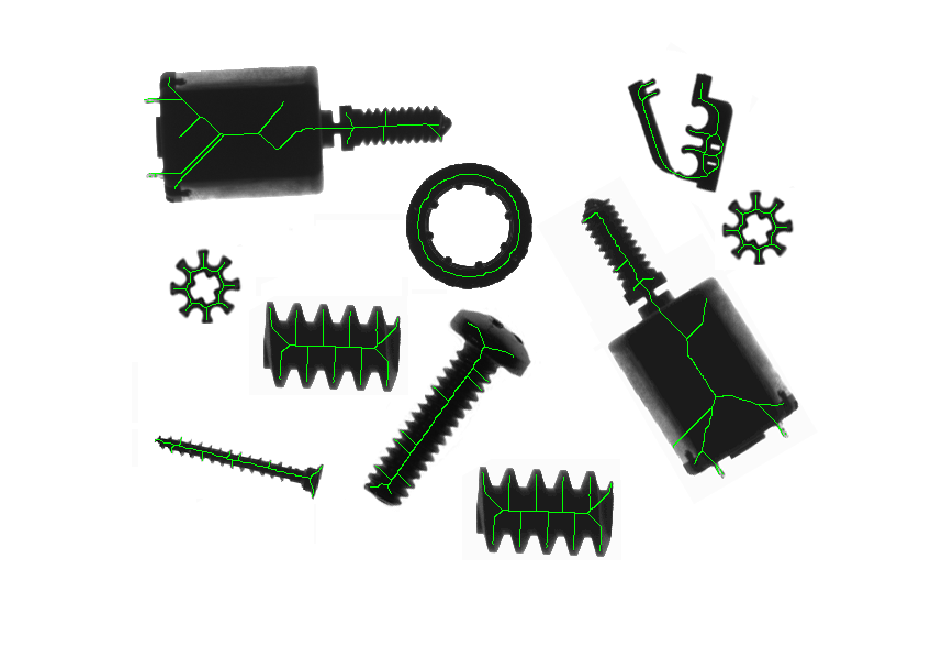

figure;
imshow (double(im1).*not(esqueleto) + esqueleto*256, [ gray(255); 0 1 0]) ;

## OPERADORES MORFOLÓGICOS

#### EJERCICIO 8

Repita el ejercicio 7 empleando adelgazamiento morfológico

esqueleto = bwmorph(im1b, 'thin', inf);
imshow(double(im1).*not(esqueleto)+256*esqueleto, [gray(255); 0 1 0]);

#### EJERCICIO 9

Aplique la siguiente secuencia de operadores morfológicos para la mejora de la imagen im2b de tal forma que sólo queden las piezas con sus huecos principales (im3b). Muestre en una figura la imagen binaria original y las tres imágenes intermedias, subplot (2,2,…)

open > dilate (5) > erode (5)

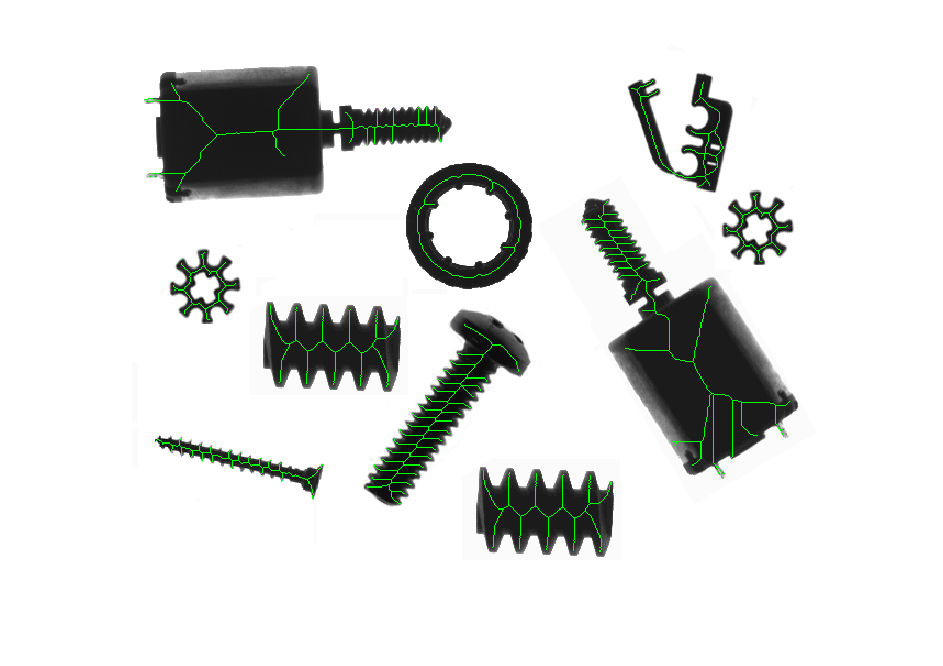

figure;
subplot(221); imshow(im2b);

subplot(222); im3b = bwmorph(im2b, 'open'); imshow(im3b);
subplot(223); im3b = bwmorph(im3b, 'dilate', 5); imshow(im3b);
subplot(224); im3b = bwmorph(im3b, 'erode', 5); imshow(im3b);

#### EJERCICIO 10

Realice y muestre el adelgazamiento morfológico de la imagen im3b. ¿Se mantiene en este resultado inalterado en número de Euler de cada objeto de la imagen im3b?

figure
esqueleto = bwmorph(im3b, 'thin', inf);
imshow(double(im2).*not(esqueleto)+256*esqueleto, [gray(255); 0 1 0]);

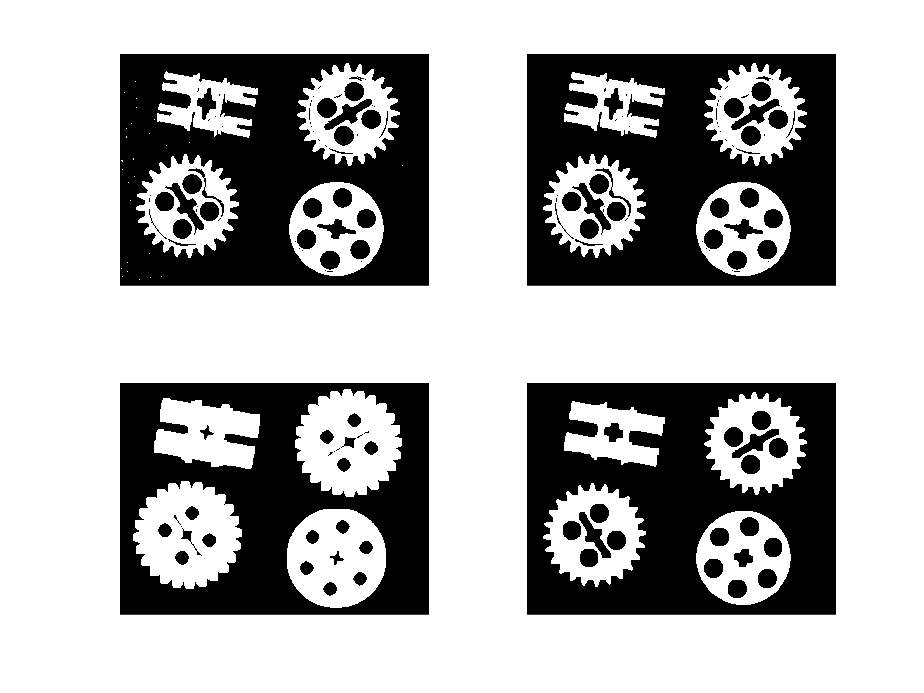

pro2 = regionprops (im2b,'Area', 'EulerNumber');
for i=1:numel(pro2)

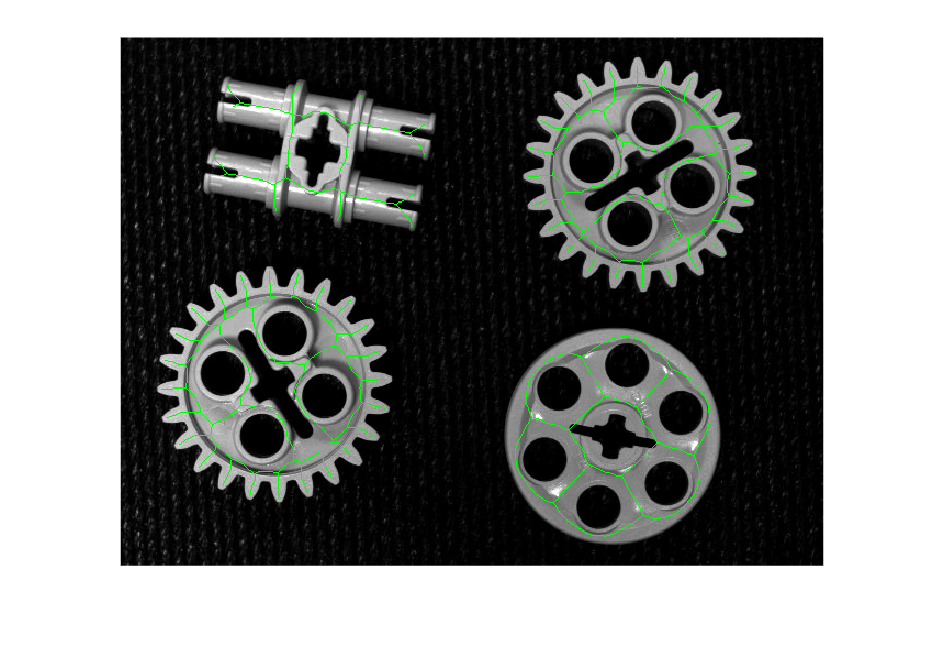

    if pro2(i).Area > 1000
        sprintf("im2b: Area=%d, Euler=%d", pro2(i).Area, pro2(i).EulerNumber)
    end
end
pro3 = regionprops (im3b,'Area', 'EulerNumber'); % e1=regionprops(im2b;'all')
for i=1:numel(pro3)

    if pro3(i).Area > 1000
        sprintf("im3b: Area=%d, Euler=%d", pro3(i).Area, pro3(i).EulerNumber)
    end
end




ans = "im2b: Area=21248, Euler=-46"

ans = "im2b: Area=14340, Euler=-17"

ans = "im2b: Area=20856, Euler=-35"

ans = "im2b: Area=21547, Euler=-60"

#### EJERCICIO 11

Cargue las imágenes de la carpeta “ .\Lcd\ ..” y aplíqueles la siguiente secuencia para la obtención del esqueleto de los dígitos para su posterior procesamiento.

- Igualación de histograma > histeq ()

- Binarización con umbral 0.25 > im2bw ()

- Negada > not ()

- Una erosión > bwmorph ()

- Cuatro dilataciones > bwmorph ()

- Adelgazamiento hasta obtener el esqueleto > bwmorph ()

load("Lcd.mat");
figure

subplot(241); im0 = lcd01; imshow(im0, []);
subplot(242); im1 = histeq(im0); imshow(im1);

ans = "im3b: Area=23696, Euler=-4"

ans = "im3b: Area=15821, Euler=0"

ans = "im3b: Area=21386, Euler=-6"

ans = "im3b: Area=23465, Euler=-4"

subplot(243); im2 = im2bw(im1, 0.25); imshow(im2);
subplot(244); im3 = not(im2); imshow(im3, []);
subplot(245); im4 = bwmorph(im3, 'erode', 1); imshow(im4);
subplot(246); im5 = bwmorph(im4, 'dilate', 4); imshow(im5);
subplot(247); im6 = bwmorph(im5, 'thin', inf); imshow(im6, []);

#### EJERCICIO 12

Muestre en una figura la imagen original y el resultado final, para todas las imágenes. ¿Cómo descartaría aquellos pixeles que no forman parte de los dígitos?

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    imshow(im0);
end

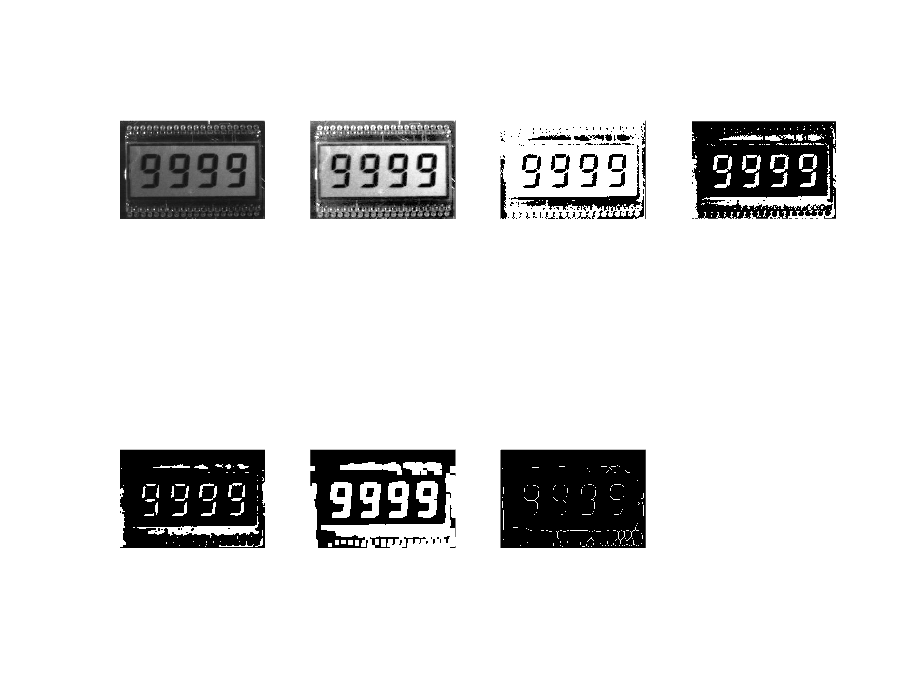

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));

    im1 = histeq(im0); 
    imshow(im1);
end

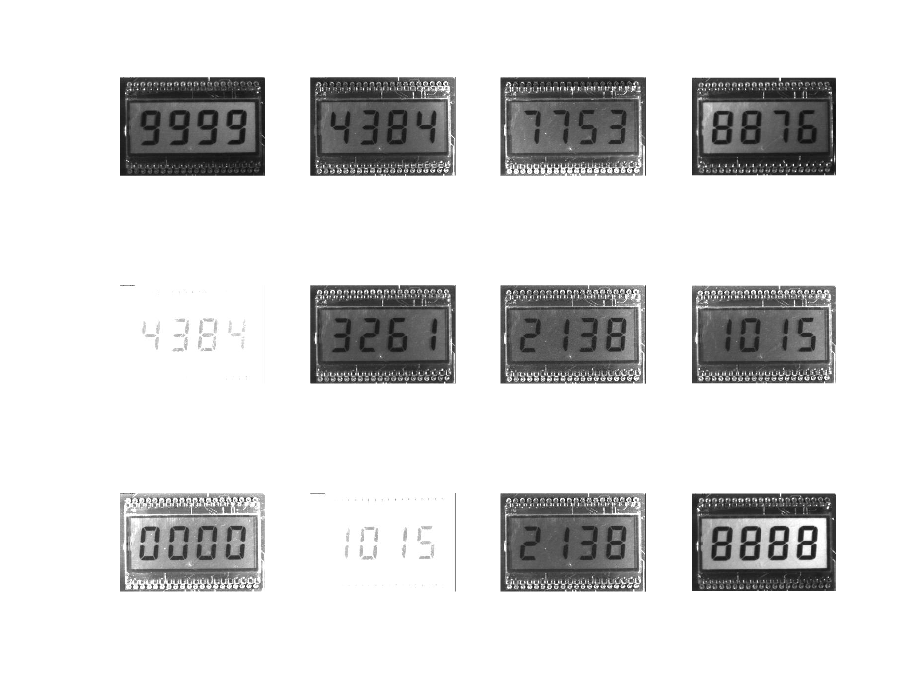

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    im1 = histeq(im0); 
    im2 = im2bw(im1, 0.25); 

    imshow(im2);
end

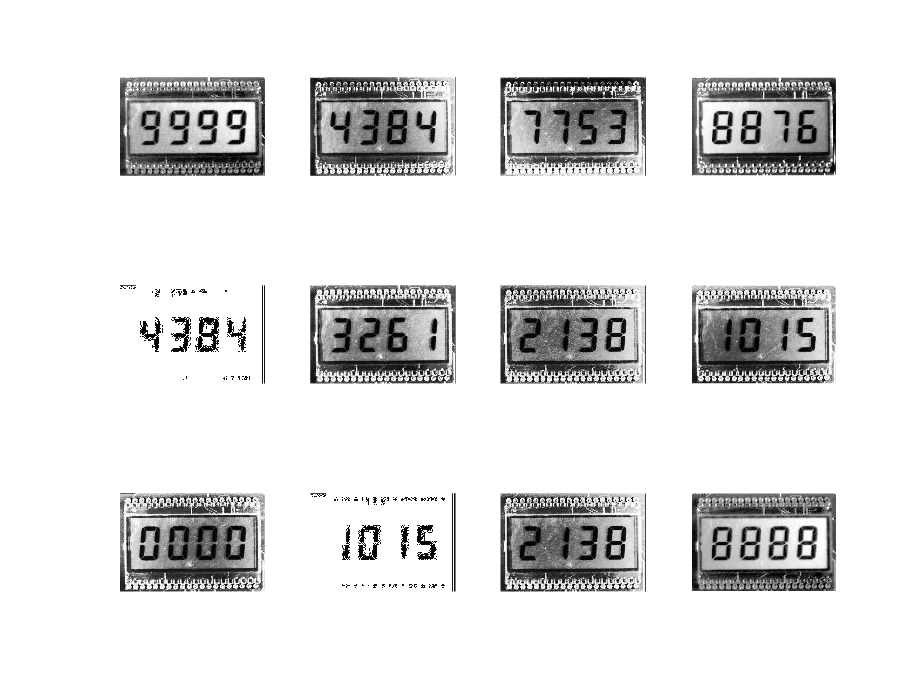

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    im1 = histeq(im0); 
    im2 = im2bw(im1, 0.25); 

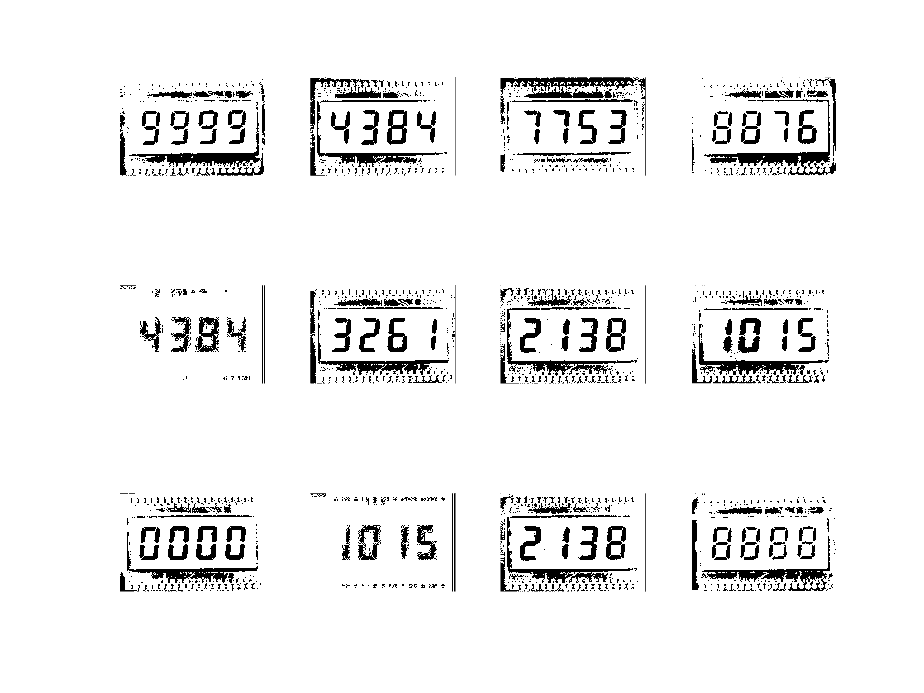

    im3 = not(im2); 
    imshow(im3, []);
end

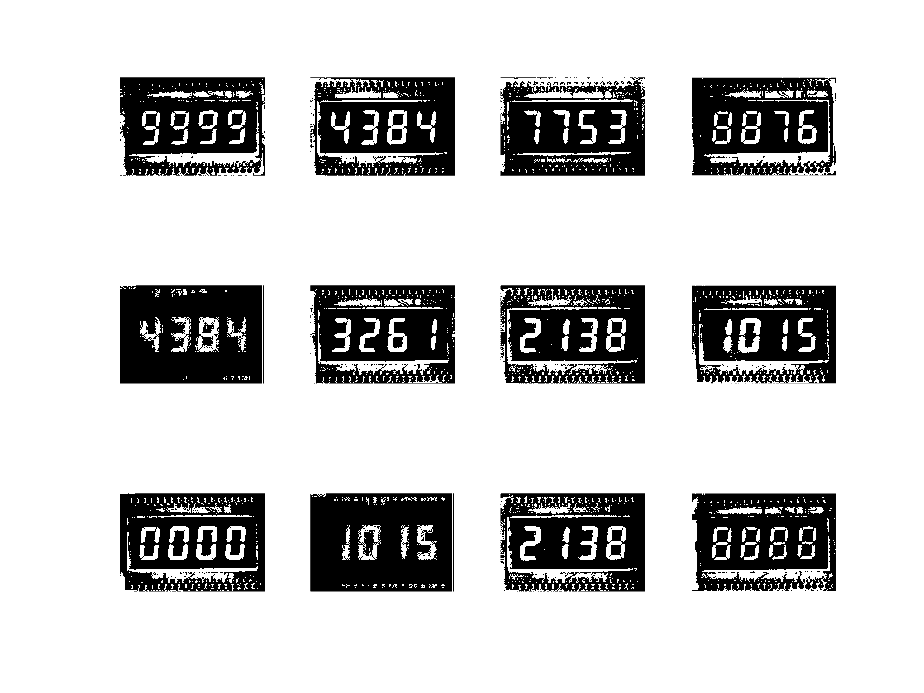

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    im1 = histeq(im0); 
    im2 = im2bw(im1, 0.25); 
    im3 = not(im2); 
    im4 = bwmorph(im3, 'erode', 1); 
    imshow(im4);

end

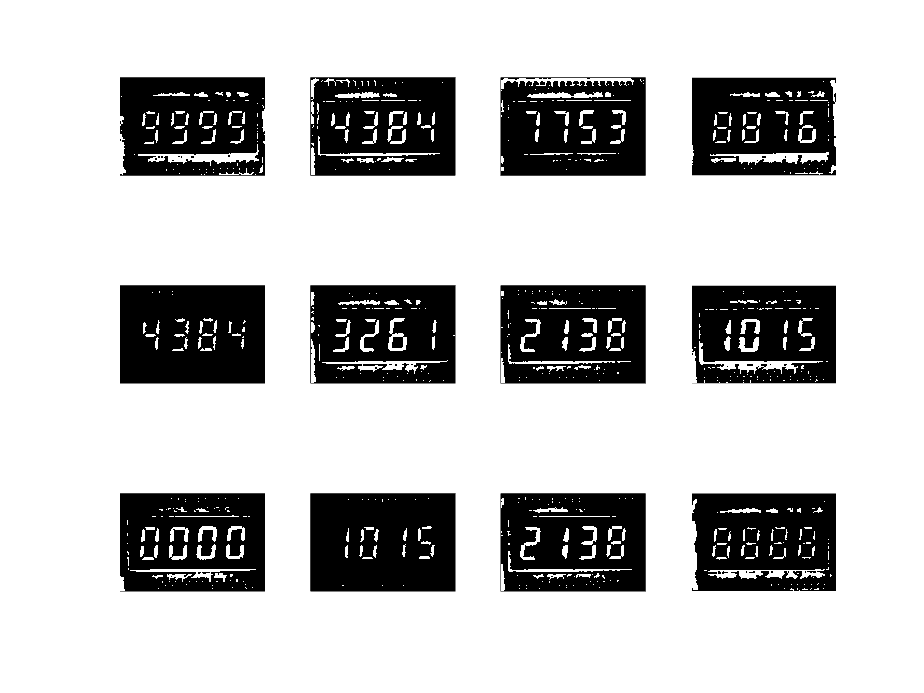

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    im1 = histeq(im0); 
    im2 = im2bw(im1, 0.25); 
    im3 = not(im2); 
    im4 = bwmorph(im3, 'erode', 1); 
    im5 = bwmorph(im4, 'dilate', 4); 
    imshow(im5);

end

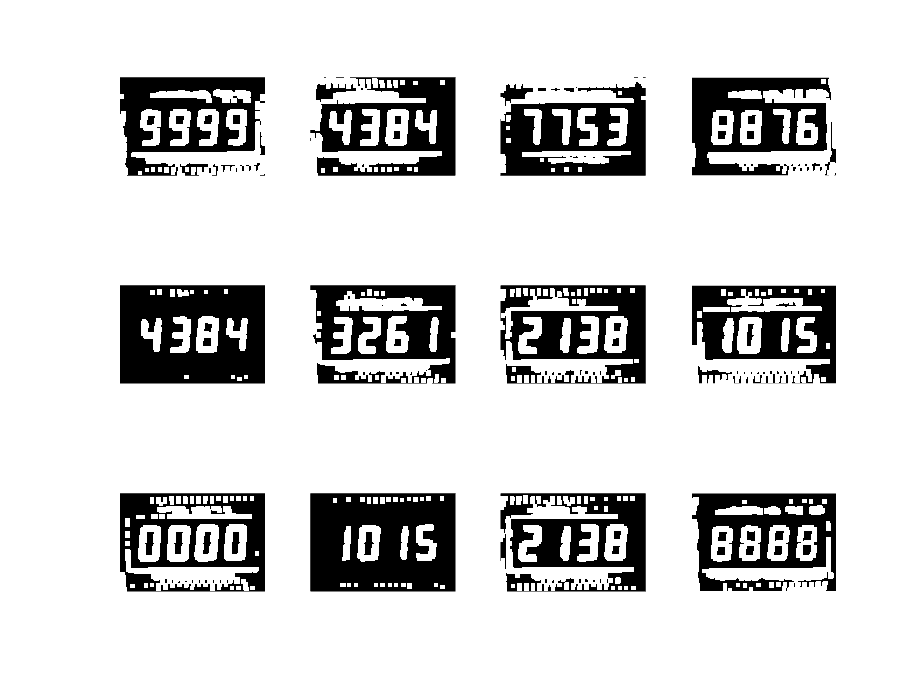

figure
for i=1:12
    subplot(3,4,i); 
    im0 = eval(sprintf("lcd%02d",i));
    im1 = histeq(im0); 
    im2 = im2bw(im1, 0.25); 
    im3 = not(im2); 
    im4 = bwmorph(im3, 'erode', 1); 
    im5 = bwmorph(im4, 'dilate', 4); 
    im6 = bwmorph(im5, 'thin', inf); 
    imshow(im6, []);

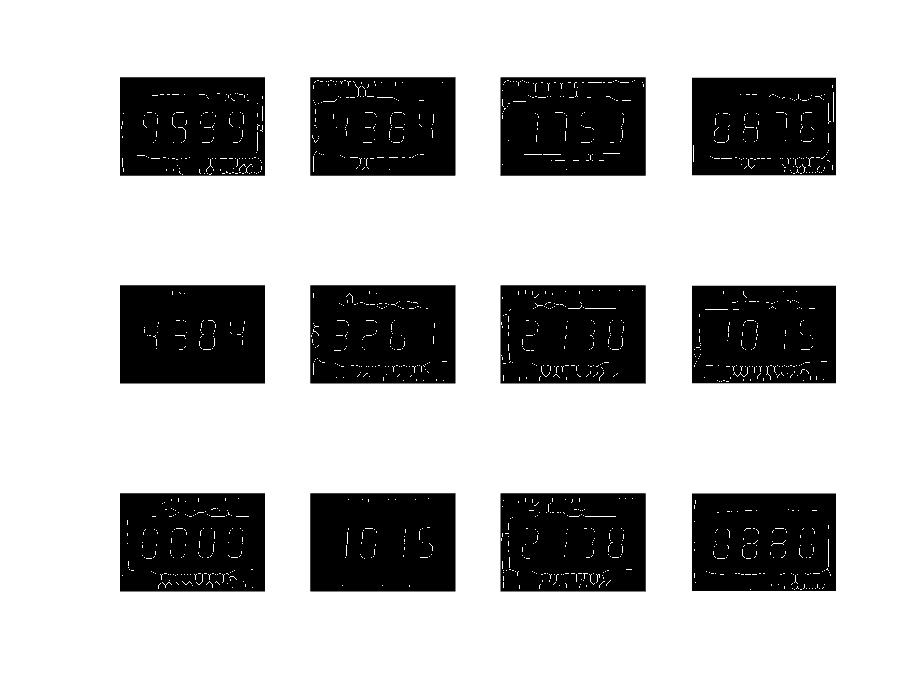

end